# Identification

### System Definition

clc 
clear all
close all

L_nom = 36.5e-6;

DuCy=30; 
I_Lo=0; V_Co=0;
Vg=5; Vd=0.7;

load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

Vs=[Vg Vd];
X=[I_Lo V_Co];


### Integer order

[A,B,C,D,G_int] =flyback_ss(Vs,X,DuCy, Lm_bm, C_bm)

A = 	1.0e+05 *

   -0.1907   -7.9101
    1.0422   -0.0000


B = 	1.0e+06 *

    1.9066    0.7910
         0         0


C =      0     1


D =      0     0


G_int =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.



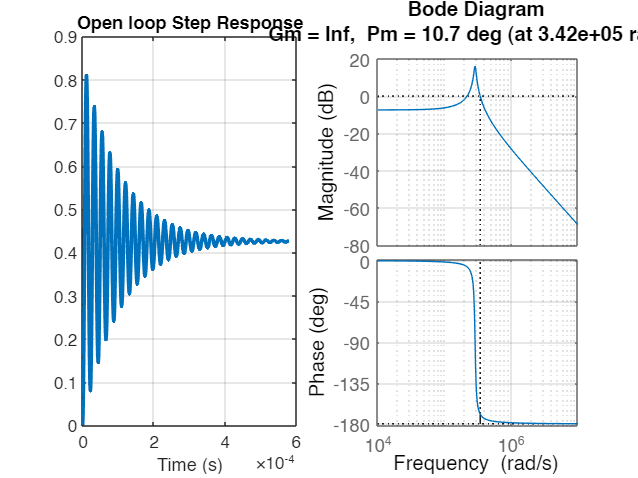

figure
subplot(1,2,1)
[y,t]=step(G_int); plot(t,y,'LineWidth',2)
grid on
title('Open loop Step Response')
xlabel('Time (s)')

subplot(1,2,2)
margin(G_int)
grid on

### Fractional order

[G_fo] = flyback_fract(Vs,X,DuCy/100)

Fractional-order transfer function:
               7
-------------------------------
5e-11s^{1.9}+5e-06s^{0.95}+1.96


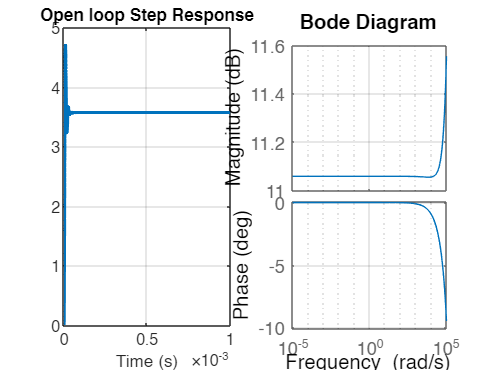


figure
subplot(1,2,1)
[y,t]=step(G_fo); plot(t,y,'LineWidth',2)
grid on
title('Open loop Step Response')
xlabel('Time (s)')

subplot(1,2,2)
bode(G_fo)
grid on

### Discretization for DT

Ts = 0.00001;
G_int_d = c2d(G_int,Ts,'tustin')

G_int_d =
 
                              
  0.3677 z^4 + 1.465 z^3      
                              
          + 2.192 z^2         
                              
            + 1.458 z + 0.3643
                              
  ----------------------------
                              
  z^4 + 3.978 z^3 + 5.945 z^2 
                              
             + 3.956 z + 0.989
                              
 
Sample time: 1e-05 seconds
Discrete-time transfer function.




G_int_d.Numerator

ans = 1×1 cell array
    {[0.3677 1.4652 2.1917 1.4584 0.3643]}


G_int_d.Denominator

ans = 1×1 cell array
    {[1 3.9779 5.9449 3.9560 0.9890]}



Kp = 0.000271;
Ti = 4.69e-10;
s=tf('s');
c = Kp*(1+1/(s*Ti))

C =
 
  1.271e-13 s + 0.000271
  ----------------------
        4.69e-10 s
 
Continuous-time transfer function.




F = feedback(c*G_int,1)

F =
 
                              
  1.271e-08 s^4 + 28.46 s^3   
                              
          + 2.896e09 s^2      
                              
          + 1.975e15 s        
                              
                    + 8.329e22
                              
  -----------------------------
                               
  4.69e-10 s^5 + 0.0003752 s^4 
                               
          + 2.719e04 s^3       
                               
          + 1.373e10 s^2       
                               
          + 3.931e17 s         
                               
                    + 8.329e22 
                               
 
Continuous-time transfer function.



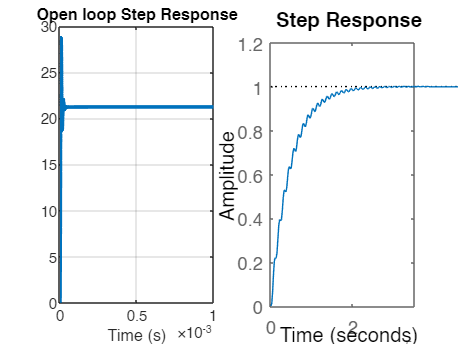

step(F)